# Tutorial

The function fred_api() allows users to conveniently download economic time series data from the FRED (Federal Reserve Economic Data) online database maintained by the Research Department at the Federal Reserve Bank of St. Louis. The data are accessed by connecting directly to the FRED data server (https://fred.stlouisfed.org).

The selected series are returned into a timetable. When multiple series are requested by the user, they are all merged together and returned into the same timetable. Merging returns the union (rather than the intersection) of the dates of the selected series. If a series is shorter than the rest of the requested series, the absent observations are set into missing (NaN). Similarly, series of different frequencies can also be requested in the same function call, and missing observations (that are due to the frequency mismatch) are treated in the same manner. The user can request the desired range of dates by setting the Name-Value pairs 'StartDate' and 'EndDate'. If no range is specified, the function retrieves all the observations available in FRED for the selected series. 

%SYNTAX:
%[TT, Meta] = fred_api(fred_code, 'StartDate',startdate, 'EndDate',enddate);

%INPUTS:
%- 'fred_code': The FRED mnemonic(s) of the requested series.
%- 'StartDate': Specifies the series starting date. If the input is 
%               omitted, the function returns the earliest starting date 
%               available in FRED. The input should be specified as a 
%               datetime e.g. datetime(2021,3,31) for 31st March 2021.
%- 'EndDate':   Specifies the series ending date. If the input is omitted,
%               the function returns the latest ending date available in 
%               FRED. The input should be specified as a 
%               datetime

%OUTPUTS:
%- 'TT':   A timetable of size T-by-N containing the timeseries, where N is 
%          the number of the specified FRED series in 'fred_seriescode'. 
%          The dates in the resulted timetable are in DD/MM/YYYY format.
%- 'Meta': A N-by-10 sized table containing metadata information for the 
%          N requested variables. Specifically, the following information 
%          is retruned in the table: 
%           DateRange, Frequency, LastUpdated, Notes, Release, 
%           SeasonalAdjustment, SeriesID, Source, Title, Units.

## **Examples**

%-----------------------------%
% (A) Request a single series %
%-----------------------------%

%- Retrieve all the available dates
fred_code = 'CPIAUCSL';  %CPI Inflation (monthly)
[TT, Meta] = fred_api(fred_code);
[TT, Meta] = fred_api(fred_code, 'StartDate',NaT,'EndDate',NaT); %Equivalent to above
[TT, Meta] = fred_api(fred_code, 'StartDate',[],'EndDate',[]);   %Equivalent to above
[TT, Meta] = fred_api(fred_code, 'StartDate',[],'EndDate',datetime('now'));  %Equivalent to above

%Print the last 5 rows
TT(end-4:end, :) 

ans = 5×1 timetable
       Time       CPIAUCSL
    __________    ________
    01/03/2022     287.71 
    01/04/2022     288.66 
    01/05/2022     291.47 
    01/06/2022     295.33 
    01/07/2022     295.27 

%Print selected metadata
Meta(:, ["DateRange","Frequency","LastUpdated","Units","SeasonalAdjustment"])

ans = 1×5 table
            DateRange             Frequency          LastUpdated                   Units             SeasonalAdjustment  
    __________________________    _________    ________________________    _____________________    _____________________
    "1947-01-01 to 2022-07-01"    "Monthly"    "2022-08-10 7:38 AM CDT"    "Index 1982-1984=100"    "Seasonally Adjusted"

%- Retrieve selected range (from startdate to enddate)
fred_code = 'CPIAUCSL';
startdate = datetime(2020,1,1);
enddate = datetime(2020,12,1);
[TT, Meta] = fred_api(fred_code, 'StartDate',startdate, 'EndDate',enddate);

%Print the entire table
TT(:,:) 

ans = 12×1 timetable
       Time       CPIAUCSL
    __________    ________
    01/01/2020     258.68 
    01/02/2020     259.01 
    01/03/2020     258.17 
    01/04/2020     256.09 
    01/05/2020     255.94 
    01/06/2020     257.22 
    01/07/2020     258.54 
    01/08/2020     259.58 
    01/09/2020     260.19 
    01/10/2020     260.35 
    01/11/2020     260.72 
    01/12/2020     261.56 

%Return the series as a numerical vector (instead of timetable)
TT{:,:}

ans =   258.6820
  259.0070
  258.1650
  256.0940
  255.9440
  257.2170
  258.5430
  259.5800
  260.1900
  260.3520


%-----------------------------%
% (B) Request multiple series %
%-----------------------------%

%- Request SAME-FREQUENCY variables
fred_code = ["INDPRO","IPB50001N","UNRATE"]; %3 monthly series
[TT, Meta] = fred_api(fred_code, 'StartDate',datetime(2000,1,1), 'EndDate',datetime(2020,3,1));

%Print the last 5 rows
TT.Time.Format = 'dd-MMM-yyyy'; %Change the display format of dates
TT(end-4:end, :)

ans = 5×3 timetable
       Time        INDPRO    IPB50001N    UNRATE
    ___________    ______    _________    ______
    01-Nov-2019     102.1     101.58       3.6  
    01-Dec-2019    101.76     101.77       3.6  
    01-Jan-2020     101.3     101.29       3.5  
    01-Feb-2020     101.7     102.01       3.5  
    01-Mar-2020    97.875     98.092       4.4  

%Print selected metadata
Meta(:, ["Frequency","Units","SeasonalAdjustment"])

ans = 3×3 table
    Frequency         Units             SeasonalAdjustment    
    _________    ________________    _________________________
    "Monthly"    "Index 2017=100"    "Seasonally Adjusted"    
    "Monthly"    "Index 2017=100"    "Not Seasonally Adjusted"
    "Monthly"    "Percent"           "Seasonally Adjusted"    

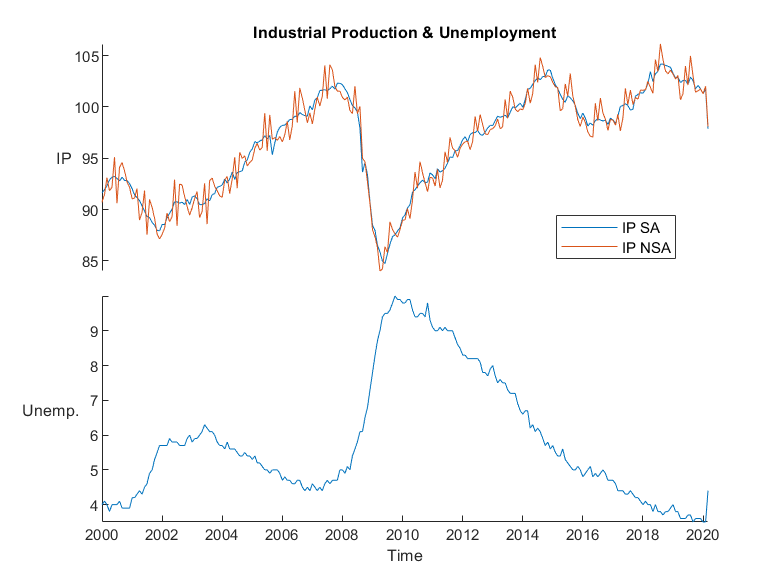

%Plot the series
p = stackedplot(TT,{["INDPRO" "IPB50001N"] "UNRATE"});
p.Title = 'Industrial Production & Unemployment';
p.DisplayLabels = {'IP','Unemp.'};
p.AxesProperties(1).LegendLabels = ["IP SA","IP NSA"];
p.AxesProperties(1).LegendLocation = 'SouthEast';

%- Request variables of DIFFERENT FREQUENCIES
fred_code = ["INDPRO","GDPC1"];  %1 monthly & 1 quarterly series
[TT, Meta] = fred_api(fred_code, 'StartDate',datetime(2000,1,1), 'EndDate',datetime(2022,6,1));

%Print the last 8 rows
TT(end-7:end, :)

ans = 8×2 timetable
       Time       INDPRO    GDPC1
    __________    ______    _____
    01/11/2021    101.96      NaN
    01/12/2021    101.76      NaN
    01/01/2022    102.15    19728
    01/02/2022     102.9      NaN
    01/03/2022    103.62      NaN
    01/04/2022     104.3    19699
    01/05/2022    104.21      NaN
    01/06/2022    104.22      NaN

%Print selected metadata
Meta(:, ["Frequency","Units","SeriesID"])

ans = 2×3 table
     Frequency                   Units                   SeriesID
    ___________    __________________________________    ________
    "Monthly"      "Index 2017=100"                      "INDPRO"
    "Quarterly"    "Billions of Chained 2012 Dollars"    "GDPC1" 

%Fill the quarterly series by repeating within-period values
TT(:,"GDPC1") = fillmissing(TT(:,"GDPC1"),'previous');

%Print the last 8 rows
TT(end-7:end, :)

ans = 8×2 timetable
       Time       INDPRO    GDPC1
    __________    ______    _____
    01/11/2021    101.96    19806
    01/12/2021    101.76    19806
    01/01/2022    102.15    19728
    01/02/2022     102.9    19728
    01/03/2022    103.62    19728
    01/04/2022     104.3    19699
    01/05/2022    104.21    19699
    01/06/2022    104.22    19699

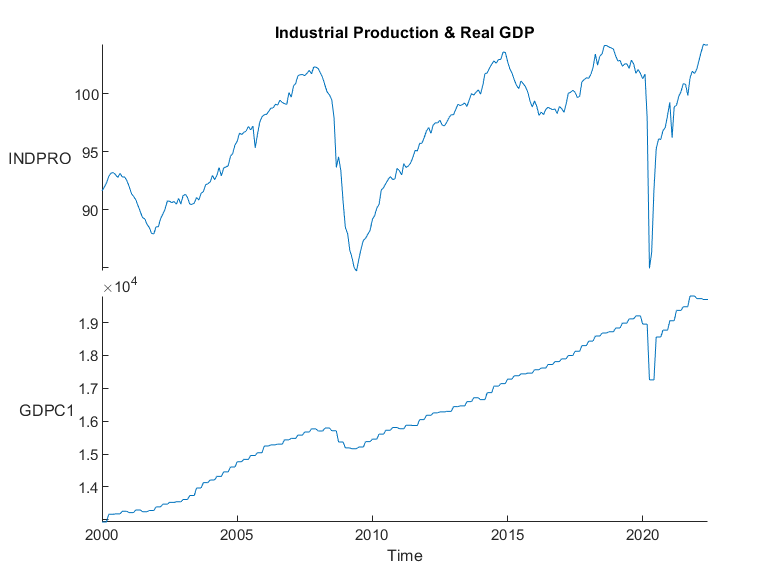

%Plot the series in separate panels
p = stackedplot(TT);
p.Title = 'Industrial Production & Real GDP';

Author: Haris Karagiannakis 